# CHW03 - Signals & Systems - 401110448 - Mohammad Sadra Hosseini

## Q1.

1.1

first define transfer functions using symbolic toolbox:

clc, clear, close all
syms s;
syms H1(s) H2(s);
H1(s) = (s - 1) / (s ^ 3 + 20 * s ^ 2 + 10 * s + 100);
H2(s) = 1 / (s ^ 4 + 20 * s ^ 2 + 10 * s + 100);

for calculate zeros and poles first seperate numerator and denominator of fraction using numden function:

[zeros_1, poles_1] = numden(H1);
[zeros_2, poles_2] = numden(H2);

for calculate the actual value of zeros and poles we must solve above expressions using vpa and solve function:

eqn = zeros_1 == 0;
fprintf('zero(s) of H1 transfer function is(are) : %s\n', vpa(solve(eqn)));

zero(s) of H1 transfer function is(are) : 1.0


eqn = poles_1 == 0;
fprintf('pole(s) of H1 transfer function is(are) : %s\n', vpa(solve(eqn)));

pole(s) of H1 transfer function is(are) : - 0.12497997765553799881119491960985 - 2.2466999973790039553692233417154i
pole(s) of H1 transfer function is(are) : - 0.12497997765553799881119491960985 + 2.2466999973790039553692233417154i
pole(s) of H1 transfer function is(are) : -19.75004004468892400237761016078


eqn = poles_2 == 0;
fprintf('pole(s) of H2 transfer function is(are) : %s\n', vpa(solve(eqn)));

pole(s) of H2 transfer function is(are) : - 0.62276434684117292020392327821602 + 2.5245743971491028257334919893662i
pole(s) of H2 transfer function is(are) : - 0.62276434684117292020392327821602 - 2.5245743971491028257334919893662i
pole(s) of H2 transfer function is(are) : 0.62276434684117292020392327821602 + 3.7950223947497687310341773420827i
pole(s) of H2 transfer function is(are) : 0.62276434684117292020392327821602 - 3.7950223947497687310341773420827i


for draw zeros-poles graph, i use zplane function. first must convert every polynomial to an array includes its coefficients using sym2poly and roots functions and then plot them: 

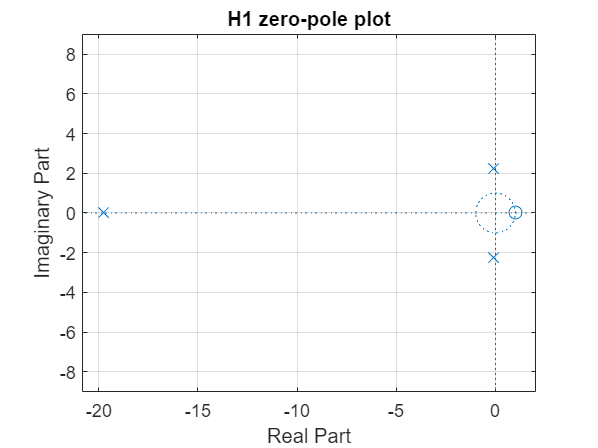

zeros_1 = roots(sym2poly(zeros_1));
zeros_2 = roots(sym2poly(zeros_2));
poles_1 = roots(sym2poly(poles_1));
poles_2 = roots(sym2poly(poles_2));

figure;
zplane(zeros_1, poles_1);
grid on
title('H1 zero-pole plot');

from above graph i find out the first system is stable because all of poles are in Left Half Plane.

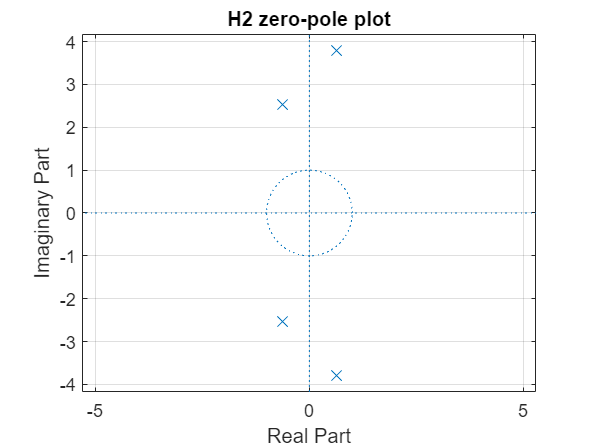

figure;
zplane(zeros_2, poles_2);
grid on
title('H2 zero-pole plot');

from above graph i find out the second system is unstable because two poles are in the Right Half Plane.

1.2

tf function obeys below syntax,

"Specify the numerator and denominator coefficients ordered in descending powers of `s"(`matlab's help for tf function`).`

for multiply paranthesis`, `i use 1 dimensional convolution. after that, use tf function with 2 arguments, numerator coefficients and denominator coefficients. this function returns a system object that we can put it in pzmap function.

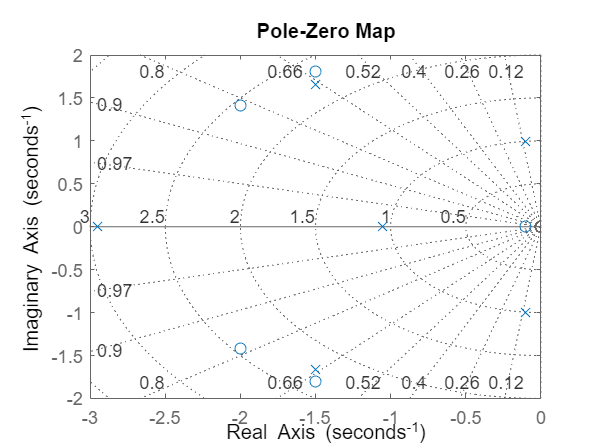

num1 = [1 3 5.5];
num2 = [1 4 6];
num3 = [1 0.2 0.01];
num = conv(conv(num1, num2), num3);

den1 = [1 3 5];
den2 = [1 4 3.1];
den3 = [1 0.2 1];
den = conv(conv(den1, den2), den3);

H3 = tf(num, den);

figure;
pzmap(H3);
grid on

1.3

we know that


$$h(t) = L^{-1}\{H(s)\}$$


that h is impulse response and H is transfer function and also we know that


$$sr(t) = L^{-1}\{\frac{H(s)}{s}\}$$


that sr is unit step response of system. using this property:

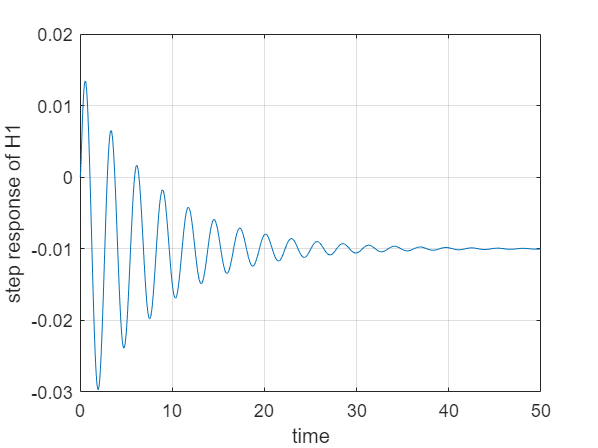

syms t;
step_1 = ilaplace(H1 / s, s, t);
step_2 = ilaplace(H2 / s, s, t);

figure;
t1 = linspace(0, 50, 1000);
plot(t1, subs(step_1, t, t1));
grid on
xlabel('time');
ylabel('step response of H1');

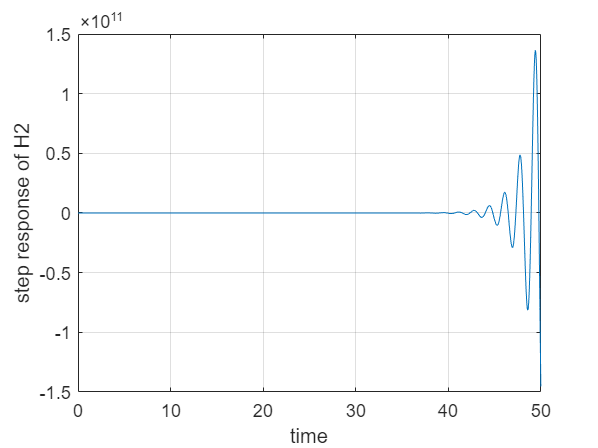


figure;
plot(t1, subs(step_2, t, t1));
grid on
xlabel('time');
ylabel('step response of H2');

we know that if all of poles be in left of imaginary axis, then system is stable and vice versa.

so from first graph we can see that H1 is stable, also from its zero-pole plot we can understand that.

from second graph we can see that H2 increases in time so it isn't stable, also from its zero-pole we can understand that because two of poles are in the right side of imaginary axis.

1.4

using properties previous part properties, first retrieve impulse and step response of G(s, a) for every a and then plot it:

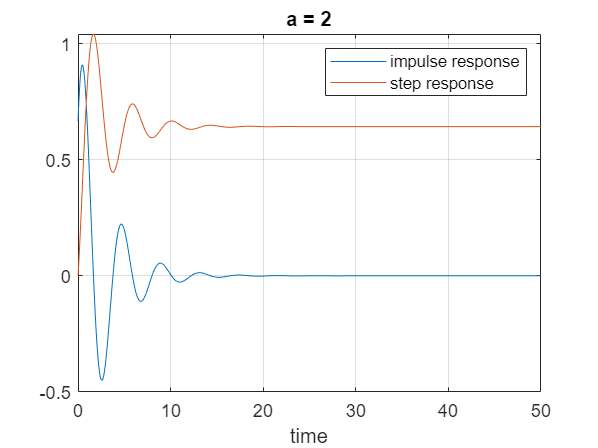

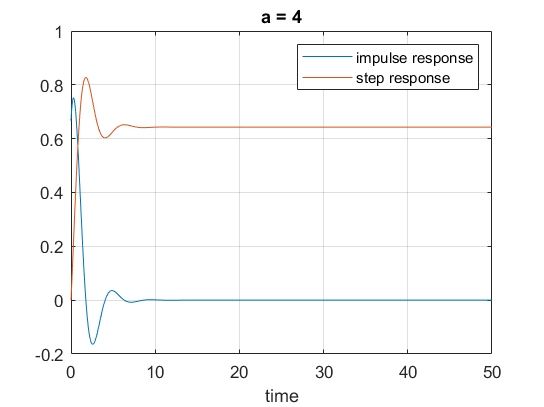

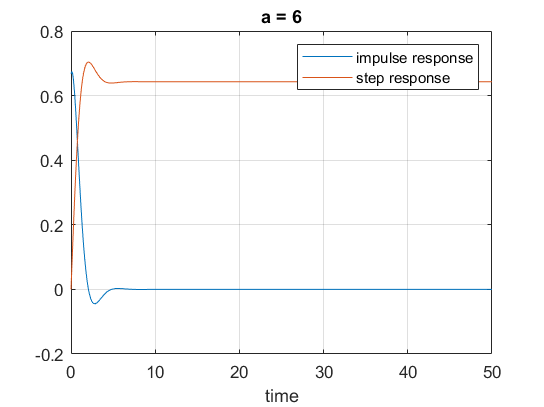

syms a G(s, a);
G(s, a) = (2 * s + 4.5) / (3 * s ^ 2 + a * s + 7);

list_a = [2 4 6];
for i = 1 : length(list_a)
    impulse_sys = ilaplace(G(s, list_a(i)), s, t);
    step = ilaplace(G(s, list_a(i)) / s, s, t);
    
    figure;
    plot(t1, subs(impulse_sys, t, t1));
    hold on
    plot(t1, subs(step, t, t1));
    grid on
    xlabel('time');
    title(sprintf('a = %i', num2str(list_a(i)) - 48));
    legend('impulse response', 'step response');
end    

first thing we can see from graphs is impulse response is derivation of step response(every optimum point of step response is a zero in impulse graph). increament in 'a' will show itself in smoothness of graph. in other words when we increase 'a' then number of optimum points(changes in second derivative) will decrease.

if 'a' increase, responses will converge to their final value quickly.

## Q2.

2.1

first define our symbolic function and then apply ztrans function on it for get Z transform of our signal. for plot pole-zero map, first i make a system object using tf(for discrete systems, we must put a sampling time 't_s' in third argument) and then plot using pzmap function:

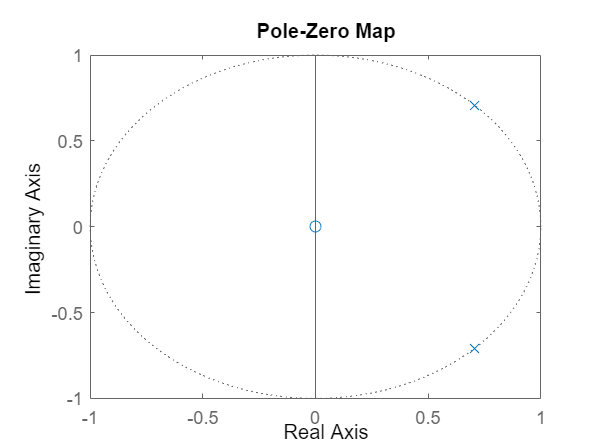

clc, clear, close all
syms n x(n);
x(n) = sin(n * pi / 4);
syms z X(z);
X(z) = ztrans(x, n, z);
[zeros, poles] = numden(X);
zeros = sym2poly(zeros);
poles = sym2poly(poles);

ts = 0.1;
system = tf(zeros, poles, 0.1);
figure;
pzmap(system);

2.2

from zero-pole map we understand that ROC will be out of outermost pole, for two reasons, first our signal is casual and second ROC won't contain any pole:


$$|z| > 1$$


2.3

in this method, we simplify and then seperate our z transform into two parts:


$$H(z) = \sum_{i} \frac{r_i}{1 - p_i z^{-1}} + \sum_i k_i z^{-i}$$
 

so the inverse transform of above system is (i assume our system is casual)


$$h[n] = \sum_i r_i (p_i)^n u[n] + \sum_i k_i \delta[n - i + 1] $$


use above property we can go to time domain:

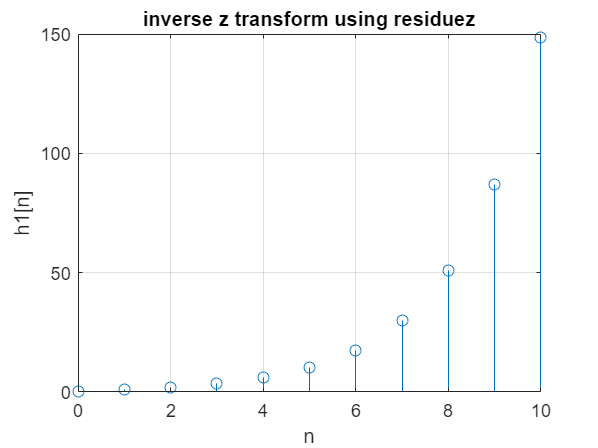

syms H1(z);
num = [0 1];
den = [1 -2 0.5];
[r, p, k] = residuez(num, den);
syms h1(n);
h1(n) = 0;
for i = 1 : length(r)
    h1(n) = h1(n) + r(i) * p(i) ^ n;
end    

for i = 1 : length(k)
    h1(n) = h1(n) + k(i) * kroneckerDelta(n - i + 1);
end    

figure;
n1 = linspace(0, 10, 11);
stem(n1, subs(h1, n, n1));
xlabel('n');
ylabel('h1[n]');
title('inverse z transform using residuez');
grid on

2.4

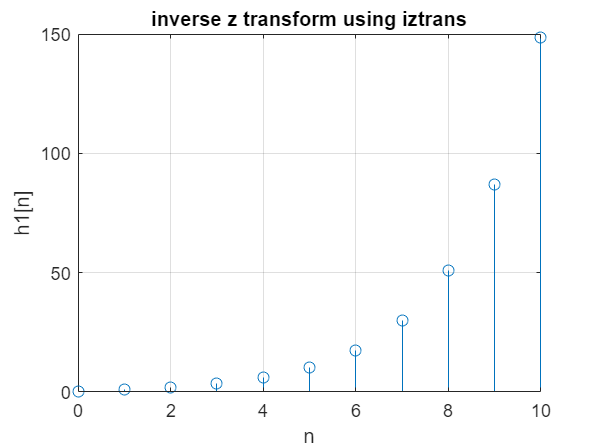

H1 = (z ^ (-1)) / (1 - 2 * z ^ (-1) + 0.5 * z ^ (-2));
H1 = z / (z ^ 2 - 2 * z + 0.5);
h1 = iztrans(H1, z, n);

figure;
n1 = linspace(0, 10, 11);
stem(n1, subs(h1, n, n1));
xlabel('n');
ylabel('h1[n]');
grid on
title('inverse z transform using iztrans');

as we can see from above plots, results are the same.

## Q3.

3.1

first read and show image using imread and imshow functions:

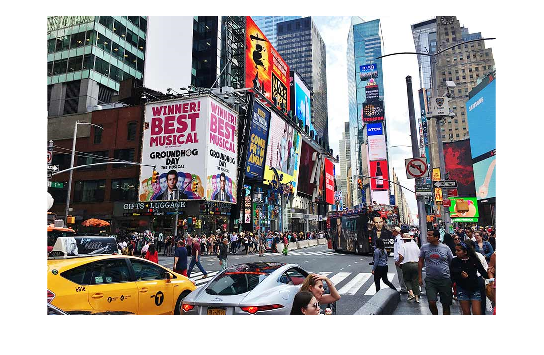

clc, clear, close all
image = imread('image.png');
figure;
imshow(image);

3.2

a rgb image is a 3 order tensor. for extract each channel, we can use notation:

$A(:, :, i)$ means that from tensor A, choose every column and every row from i-th component.

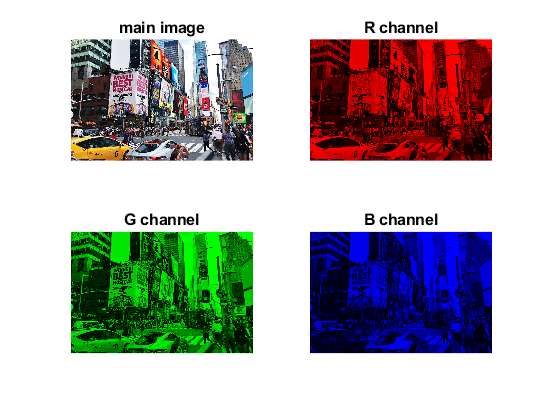

[m, n, k] = size(image);
R = zeros(m, n, k);
G = zeros(m, n, k);
B = zeros(m, n, k);

R(:, :, 1) = image(:, :, 1);
G(:, :, 2) = image(:, :, 2);
B(:, :, 3) = image(:, :, 3);

figure;
subplot(2, 2, 1)
imshow(uint8(image));
title('main image');

subplot(2, 2, 2)
imshow(uint8(R));
title('R channel');

subplot(2, 2, 3)
imshow(uint8(G));
title('G channel');

subplot(2, 2, 4)
imshow(uint8(B));
title('B channel');

3.3

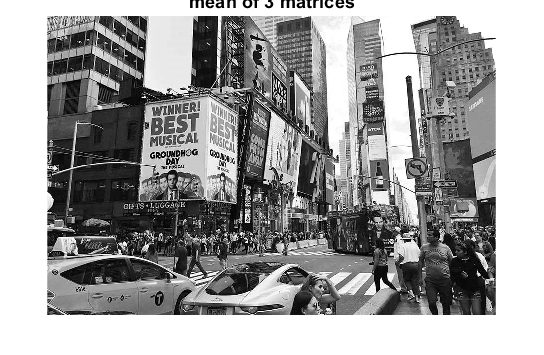

r = image(:, :, 1);
g = image(:, :, 2);
b = image(:, :, 3);

mean_image = 1 / 3 * r + 1 / 3 * g + 1 / 3 * b;

figure;
imshow(uint8(mean_image));
title('mean of 3 matrices');

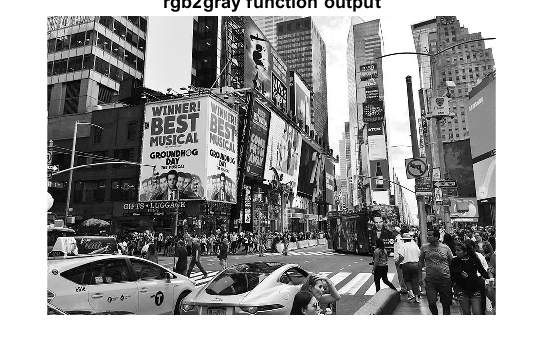


rgb_converted = rgb2gray(image);
figure;
imshow(rgb_converted);
title('rgb2gray function output');

from the results, we can see rgb2gray's output has more contrast and mean's output has more brighness than another one. this happens because when we retrieve mean of these three matrix we sum all channels with equal coefficient but rgb function calculate every element by below formula


$$0.2989 * R + 0.5870 * G + 0.1140 * B$$


these coefficients use because our eyes have different sensivity against these channels.

3.4

for convolve image with kernels, i use conv2 function. second argument is the kernel and first argument must be the image but we can't use a tensor for this function, so first convert our image to grayscale and change to double form for calculations.

after convolution we must divide result by maximum element of matrix, because after convolution brightness may too increase and after this we normalize our result and control brightness.

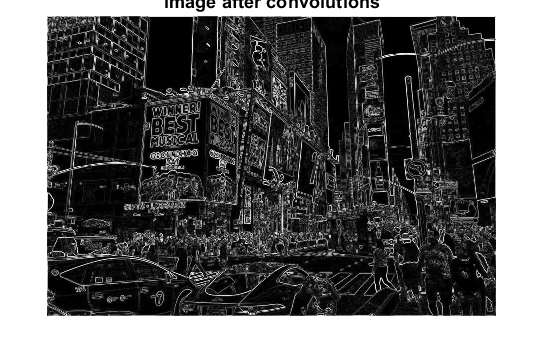

filter1 = [1 0 -1; 2 0 -2; 1 0 -1];
filter2 = [1 2 1; 0 0 0; -1 -2 -1];

G_x = conv2(im2double(rgb2gray(image)), filter1, 'full');
G_y = conv2(im2double(rgb2gray(image)), filter2, 'full');

G = sqrt(G_y .^ 2 + G_x .^ 2);
G = G / max(max(G));

figure;
imshow(G)
title('image after convolutions');

for understand the kind of filter, we know that if a filter detect edges of an image, then the filter is a highpass filter, so this filter is a highpass filter.